# Deep Learning - COVID-19.

Actualmente, el COVID-19 es una de las mayores preocupaciones para la sociedad, por lo que se ha convertido en una prioridad para muchos campos de investigación. En relación con el diagnostico de este virus y las infecciones pulmonares que produce, una de las pruebas utilizadas para extraer evidencias clinicas en su deteccion es el denominado TAC (Tomografía Axial Computarizada). El TAC pulmonar permite ver si la afección ha llegado al pulmón. Se buscan zonas aparentes visibles como "nubes".

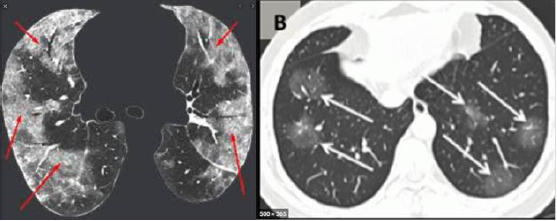

La aplicación de técnicas de aprendizaje profundo en investigación médica, cuando el diagnóstico se hace a través de imagen y hay grandes volúmenes de información disponible, es uno de los campos con más auge en la actualidad. Por ello, a partir de un conjunto de imagenes, se desarrolla una red neuronal convolucional (CNN), que permita la clasificacion de las imagenes entre positivas o negaticas en COVID-19. Y se evalua los resultados para evaluar la arquitectura.

## Carga y Exploración de las Imágenes.

En primero lugar se carga las imagenes en el espacio de trabajo, para ello se crea un fichero .zip con las carpetas con las diferentes imagenes. Se extrae y se cargan en un almacen de datos de imagen 'imds', es una forma alternativa y más rapida para trabajar con imagenes mediante su dirección de memoria. Además etiqueta automaticamente las imágenes en función de los nombres de las carpetas.

unzip('CT_COVID19.zip');

imds = imageDatastore('CT_COVID19', ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Otro metodo alternativo, es indicar acceder a los datos a través de la dirección de memoria, pero este metodo no es portable, debido a que depende de la ubicación de las carpetas.

## Carga de la Red Preentrenada.

Se carga una red preentrenada, donde se recomienda aquellas redes donde el tiempo de predicción relativa usando GPU sea menor, ya las redes requieren un alto nivel computacional. En la siguiente gráfica se observa una comparación entre las diferentes redes.

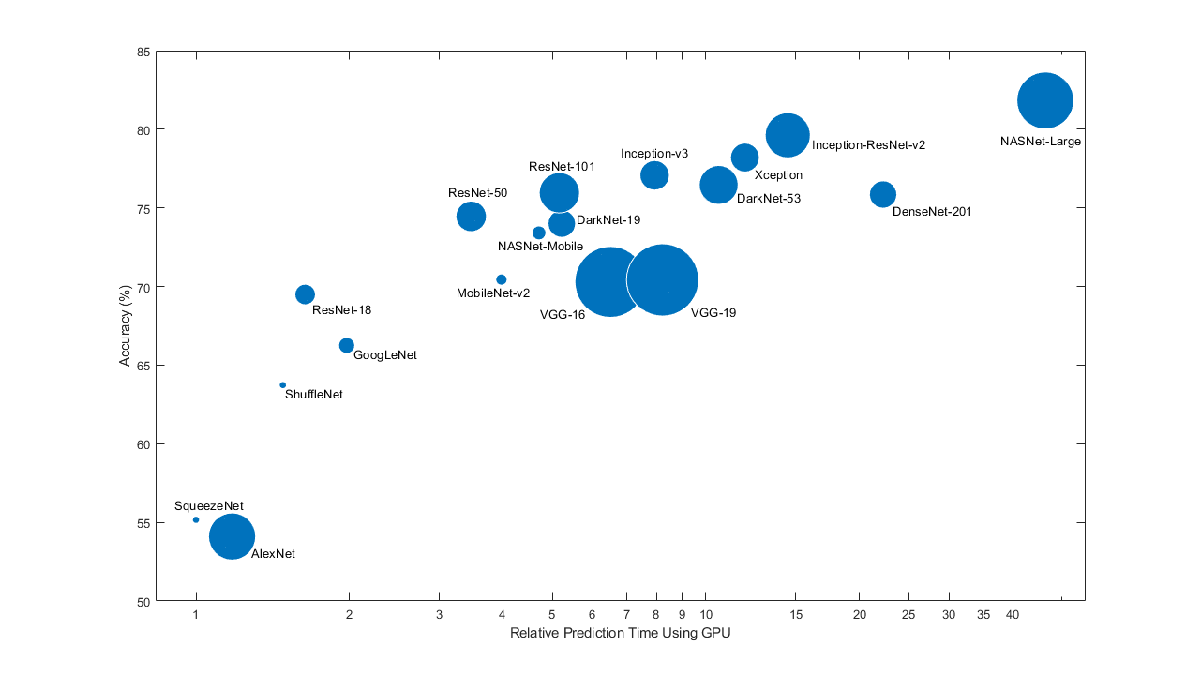

Se elige la red de GoogLeNet.

net = googlenet;

Se muestra una visualización interactiva de la arquitectura de la red e información detallada sobre las capas de la red.

analyzeNetwork(net)

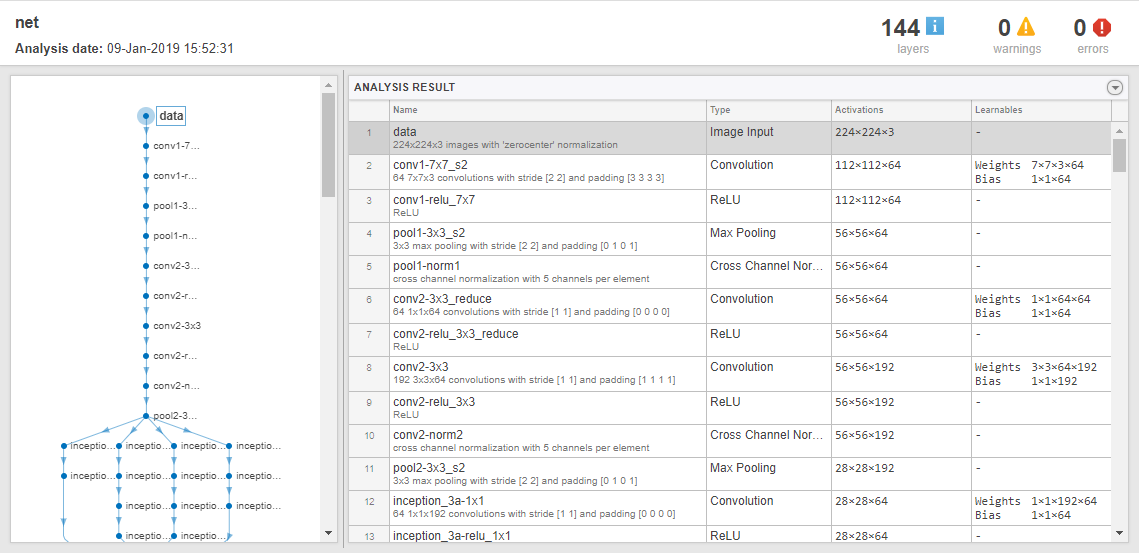

El primer elemento de la red, es la imagen de entrada. Donde se visualiza el tamaño que tiene que tener para adaptar las imagenes a la red, almacenando el tamaño en una variable, para GoogLeNet el tamaño es 224x224x3. 

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inputSize = net.Layers(1).InputSize;

## Tamaño de los Conjunto de Entrenamiento y Validación.

Se divide los datos según su función, si son para entrenar el modelo o para realizar la validación. 

Se define un 80% de datos para entreno, los cuales se seleccionan de forma aleatoria y se dividen en dos conjuntos diferentes.

numTrainFiles=0.8;
[imdsTrain, imdsValidation]=splitEachLabel(imds,numTrainFiles,'randomized');

## Reemplazar las Capas Finales.

Las capas convolucionales de la red extraen características de la imagen que la última capa puede aprender y la capa final de clasificación usan para clasificar la imagen de entrada. Estas dos capas, 'clasificador loss3' y 'salida' en GoogLeNet, contienen información sobre cómo combinar las características que la red extrae en probabilidades de clase, un valor de pérdida y etiquetas predichas. Para volver a entrenar una red preentrenada para clasificar nuevas imágenes, se reemplaza estas dos capas con nuevas capas adaptadas al nuevo conjunto de datos.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Se encuentra los nombres de las capas para reemplazar, el cual se usa la función finLayersToReplace para buscarlas de forma automatica.

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer]

ans =   1x2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

Normalmente, la ultima capa es la capa que se encuentra totalmente conectada a las neuronas anteriores, por lo que se sustituye dicha capa por una nueva completamente conectada con el número de salidas al igual que al número de clases en el nuevo conjunto de datos. Reemplazar la capa convolucional por una nueva capa convolucional con el número de filtros igual al número de clases es util para aprender más rápido en la nueva capa que en las capas transferidas, aumentando la velocidad de aprendizaje de la capa.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

La capa de clasificación especifica las clases de salida de la red.  Reemplaza la capa de clasificación por una nueva sin etiquedas.

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

Para verificar que las nuevas capas estén conectadas correctamente, se traza el nuevo gráfico de capas y se amplia las últimas capas de la red.

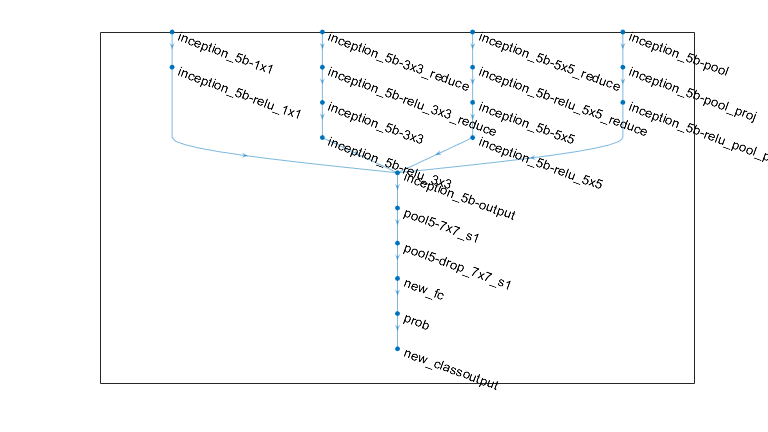

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Congelar las Capas Iniciales.

Opcionalmente, se puede congelar las capas anteriores al establecer las tasas de aprendizaje en esas capas a cero, ya que durante el entrenamiento, la red de entrenamiento no actualiza los parámetros de las capas congeladas. Debido a que los gradientes de las capas congeladas no necesitan ser calculados, congelar los pesos de muchas capas iniciales puede acelerar significativamente el entrenamiento de la red. Si el nuevo conjunto de datos es pequeño, la congelación de las capas de red puede evitar que esas capas se ajusten demasiado al nuevo conjunto de datos. 

En GoogLeNet, las primeras 10 capas conforman el 'tronco' inicial de la red, por lo que se establece las tasas de aprendizaje en cero de las 10 primeras capas, posteriormente se conecta todas las capas en el orden original. Por lo que el nuevo gráfico de capas contiene las mismas capas, pero con las tasas de aprendizaje de las capas anteriores establecidas en cero.

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

## Entrenamiento de la Red

Las imagenes de entrada tienen diferentes tamaños, por lo que se utiliza un almacén de datos de imágenes aumentadas para cambiar automáticamente el tamaño de las imágenes de entrenamiento. Para ello se accede de forma aleatoria las imágenes de entramiento a lo largo del eje vertical y transmítadas aleatoriamente hasta 30 píxeles y escalado de hasta un 10% horizontal y verticalmente. El aumento de datos ayuda a evitar que la red se sobreajuste y memorice los detalles exactos de las imágenes de entrenamiento. 

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

Para cambiar automáticamente el tamaño de las imágenes de validación y entreno sin realizar mayores aumentos de datos, use un almacén de datos de imágenes aumentadas y se realiza un proceso para pasar las imágenes a RGB, es decir, a tres canales.

augimdsTrain=augmentedImageDatastore(inputSize(1:2),imdsTrain,...
        'ColorPreprocessing','gray2rgb','DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation,...
    'ColorPreprocessing','gray2rgb');

Se especifica las opciones de entrenamiento, donde se especifica el número de épocas para entrenar, al realizar el aprendizaje de transferencia, no se necesita entrenar durante tantas épocas, por lo que se define 6 épocas. Además, se define el tamaño del mini lote y los datos de validación y se calcula la precisión de validación por cada época y se selecciona una baja tasa de aprendizaje para ralentizar el aprendizaje en las capas que aún no están congeladas. 

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

Se entrena la red utilizando los datos de entrenamiento, con las opciones indicadas.

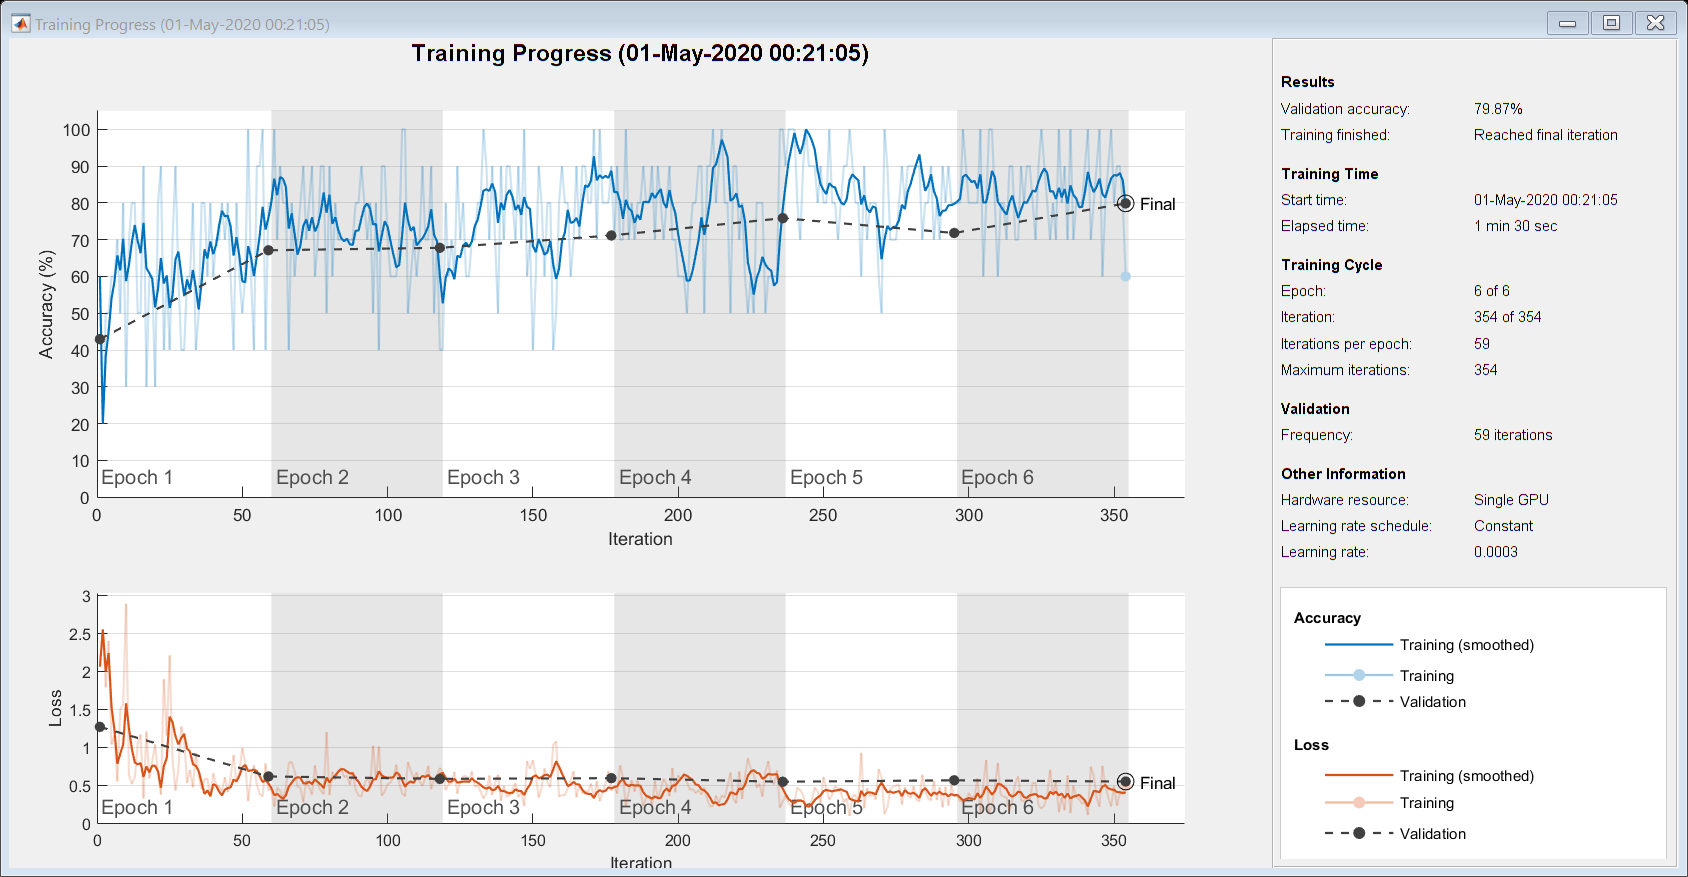

net = trainNetwork(augimdsTrain,lgraph,options);

## Clasificación de las Imágenes de Validación y Resultados.

Se predice las etiquetas de los datos de validación utilizando la red y se calcula la matriz de confusión, que gracias a ella se podrá obtener diferentes parametros para valorar la red neuronal. 

[YPred]=classify(net,augimdsValidation);
YValidation = imdsValidation.Labels;


CM=confusionmat(YPred,YValidation);

Sensitivity=CM(1,1)/(CM(1,1)+CM(2,1))

Sensitivity = 0.8143

Specificity=CM(2,2)/(CM(1,2)+CM(2,2))

Specificity = 0.7848

Accuracy=(CM(1,1)+CM(2,2))/(CM(1,1)+CM(1,2)+CM(2,1)+CM(2,2))

Accuracy = 0.7987

Precision=CM(1,1)/(CM(1,1)+CM(1,2))

Precision = 0.7703

F1Score=2*(Precision*Sensitivity)/(Precision+Sensitivity)

F1Score = 0.7917

## Fichero CSV

Se crea un fichero de texto en formato CSV con las métricas de evaluación.

filename='CT_COVID19v2.txt';
fileID=fopen(filename,'w');
fprintf(fileID,"Sensitivity,Specificity,Accuracy,Precision,F1 Score");
fprintf(fileID,"\n%f,%f,%f,%f,%f",Sensitivity,Specificity,Accuracy,Precision,F1Score);
fclose(fileID);

## Conclusión

La precisión de los datos de validación suele estar en valores en torno al 75%, consiguiendo una buena adaptación de los datos a la red de GoogLeNet para detectar el Covid-19.